# Lab 4

## Q1

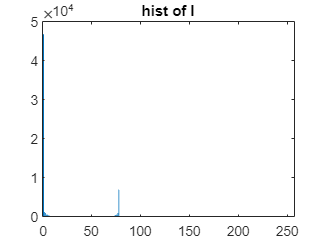

clf,clc,clear;
%1. Get PCB.gif using UI. keep for late use
%[f_name,f_path]=uigetfile();
%filepath=[f_path f_name];
%I=imread(filepath);
I=imread("PCB.gif");
Hist_I=imhist(I(:));
bar(Hist_I);
title("hist of I");

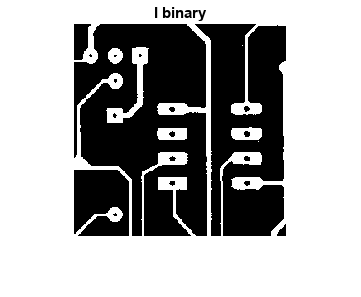

%we found that the major pixels are around 0 and 80. we will take 40.
thresh=graythresh(Hist_I)*64;
%the value is close. we got 81.8745

%2. binary convert
I_bin=I>thresh;
imshow(I_bin);
title("I binary")

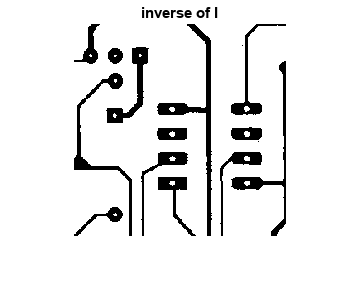

%Inverse image
not_I_bin=not(I_bin);
imshow(not_I_bin);
title("inverse of I");

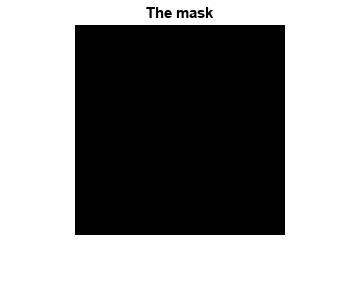

%4.
%creating one mask for the background
blackmask=zeros(size(I));
blackmask(1:end,1)=1;
blackmask(1:end,end)=1;
blackmask(1,1:end)=1;
blackmask(end,1:end)=1;
imshow(blackmask);
title("The mask");

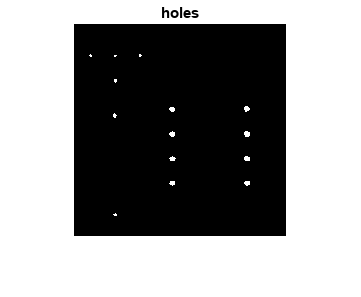


%making one label for the background
not_I_bin2=blackmask|not_I_bin;

%label the masked image
Label_not_I_bin=bwlabel(not_I_bin2);

% %debug get the number of labels
% max(max(Label_not_I_bin));

%binary convert for the holes
Label_not_I_bin=Label_not_I_bin>1;
imshow(uint8(Label_not_I_bin),[]);
title("holes");

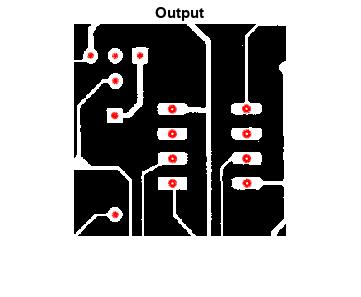




output=Label_not_I_bin|I_bin;
imshow(output);
title("Output");

%5.

%getting the stast of the objects.
stats = regionprops('table',Label_not_I_bin,'Centroid',...
    'MajorAxisLength','MinorAxisLength');

%centers- all the centers of the object
centers = stats.Centroid;
%getting the mean of major and the minor axis diameters.
diameters = mean([stats.MajorAxisLength stats.MinorAxisLength],2);
radii = diameters/2;
% %another way to calculate:
% radii=stats.MajorAxisLength/2;
hold on
viscircles(centers,radii);
hold off

## Q2

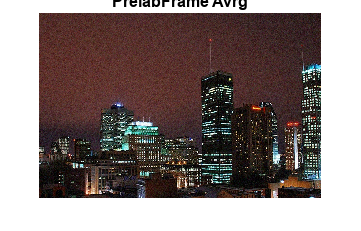

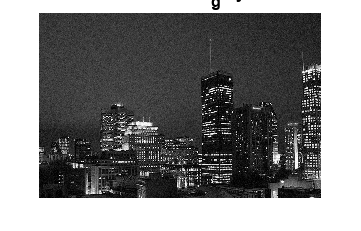

vidobj = VideoReader('Weather_Cam.avi');
numFrames = get(vidobj, 'NumberOfFrames');

%getting the best correlation
%normxcorr2(
%fit the result
%tform=fitgeotrans
%imwarp

Frame_Avrg=im2double(read(vidobj,1));
PrelabFrame_Avrg=Frame_Avrg;


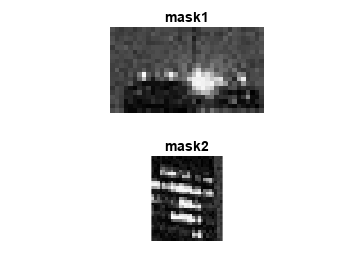

% (161, 198)  [0.44 0.25 0.26]
% (194, 216)  [0.27 0.26 0.29]
%(418, 161)  0.07
%(443, 191)  0.24

%create masks
mask = rgb2gray(Frame_Avrg);
mask1=mask([198:216], [161:194]);
mask2=mask([161:191],[418:443]);

figure();
subplot(2,1,1);
imshow(mask1);title("mask1");
subplot(2,1,2);
imshow(mask2);title("mask2");

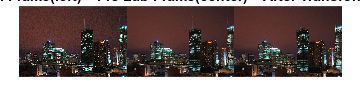


%choose points on frame
x1 = ((161 + 194)/2);
y1 = ((198 + 216)/2);
x2 = ((418 + 443)/2);
y2 = ((161 + 191)/2);

original_point= [y1 x1; y2 x2];

%transform and avrg
N_avg=16;
for i=2:N_avg
 Frame=im2double(read(vidobj, i));
 PrelabFrame=Frame;
 Frame_bw=rgb2gray(Frame);
 corr1_frame=normxcorr2(mask1,Frame_bw);
 corr2_frame=normxcorr2(mask2,Frame_bw);
 
 [shifted_y1, shifted_x1] = find(corr1_frame == max(max(corr1_frame)));
 [shifted_y2, shifted_x2] = find(corr2_frame == max(max(corr2_frame)));
 shifted_point = [shifted_y1 shifted_x1; shifted_y2 shifted_x2];
 tform = fitgeotform2d(shifted_point,original_point,"similarity");
 sameAsInput = affineOutputView(size(Frame),tform,"BoundsStyle","SameAsInput");
 imwarp(Frame,tform,"OutputView",sameAsInput);
 Frame_Avrg= Frame_Avrg+Frame;
 PrelabFrame_Avrg=PrelabFrame_Avrg+PrelabFrame;
end
PrelabFrame_Avrg=PrelabFrame_Avrg/N_avg;
Frame_Avrg= Frame_Avrg/N_avg;

%calculate std
std_Frame = std(Frame_Avrg(:));
std_Prelab = std(PrelabFrame_Avrg(:));
std_Original = std(Frame(:));

%results show
figure();
montage({Frame,PrelabFrame_Avrg,Frame_Avrg},"Size",[1 3]);
title('Original Frame(left)---Pre Lab Frame(center)---After Transform(right)');

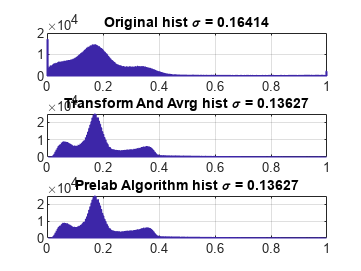


figure();
subplot(3,1,1);
hist(Frame(:),255);
title(['Original hist {\sigma} = ' num2str(std_Original)]); grid on;
subplot(3,1,2);
hist(Frame_Avrg(:),255);
title(['Transform And Avrg hist {\sigma} = ' num2str(std_Frame)]); grid on;
subplot(3,1,3);
hist(PrelabFrame_Avrg(:),255);
title(['Prelab Algorithm hist {\sigma} = ' num2str(std_Prelab)]); grid on;

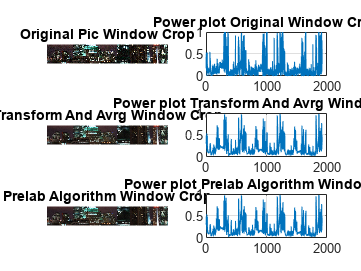


figure();
subplot(3,2,1);
imshow(Frame(250:350,:,:));
title('Original Pic Window Crop');
subplot(3,2,2);
plot(Frame(340,:));grid on;
title('Power plot Original Window Crop')

subplot(3,2,3);
imshow(Frame_Avrg(250:350,:,:));
title('Transform And Avrg Window Crop');
subplot(3,2,4);
plot(Frame_Avrg(340,:));grid on;
title('Power plot Transform And Avrg Window Crop');

subplot(3,2,5);
imshow(PrelabFrame_Avrg(250:350,:,:));
title('Prelab Algorithm Window Crop');
subplot(3,2,6);
plot(PrelabFrame_Avrg(340,:)); grid on;
title('Power plot Prelab Algorithm Window Crop');